%Traffic Flow and Congestion Patterns
%Benjamin Oakes - Engineering Computer Applications

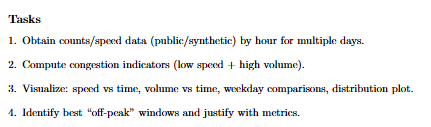



clc;                % Clears command window
clear;              % Removes all variables from workspace
close all;          % Closes all open figure windows

%% Generate Synthetic Traffic Data
time = (1:168)';    % Creates hourly data for 7 days (24*7 = 168 hours)

% Generate realistic traffic speed data
% Lower speeds during rush hour, random noise added
speed = 55 - 15*sin(time/8) + randn(size(time))*3;


volume = 250 + 100*sin(time/6) + randn(size(time))*25;

% Days of the week labels
days = ["Mon","Tue","Wed","Thu","Fri","Sat","Sun"];

% Assign each hour to a day
day = days(mod(time-1,7)+1)';

% Replace missing values if any appear
speed = fillmissing(speed,'linear');
volume = fillmissing(volume,'linear');

% Prevent unrealistic negative values
speed(speed < 0) = 0;
volume(volume < 0) = 0;

% Congestion index increases when:
% traffic volume is high AND speed is low
congestionIndex = volume ./ speed;

% Set threshold for congestion detection
threshold = mean(congestionIndex) + std(congestionIndex);

% Identify congested periods
congested = congestionIndex > threshold;

avgSpeed = mean(speed);              % Average traffic speed
maxVolume = max(volume);             % Maximum traffic volume
minSpeed = min(speed);               % Lowest speed observed
stdSpeed = std(speed);               % Speed variation

% Display metrics
fprintf('Average Speed: %.2f mph\n', avgSpeed);

Average Speed: 53.95 mph


fprintf('Maximum Volume: %.2f vehicles/hour\n', maxVolume);

Maximum Volume: 378.80 vehicles/hour


fprintf('Minimum Speed: %.2f mph\n', minSpeed);

Minimum Speed: 34.10 mph


fprintf('Speed Standard Deviation: %.2f\n', stdSpeed);

Speed Standard Deviation: 10.69


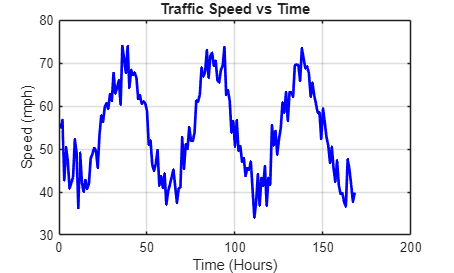


figure;
plot(time, speed, 'b', 'LineWidth', 2);    % Plot speed over time
xlabel('Time (Hours)');
ylabel('Speed (mph)');
title('Traffic Speed vs Time');
grid on;

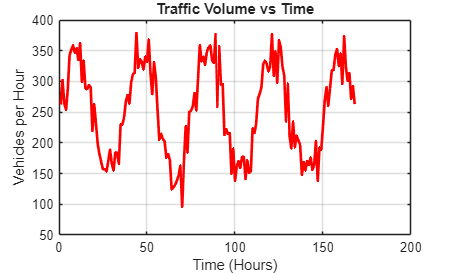


figure;
plot(time, volume, 'r', 'LineWidth', 2);   % Plot traffic volume
xlabel('Time (Hours)');
ylabel('Vehicles per Hour');
title('Traffic Volume vs Time');
grid on;

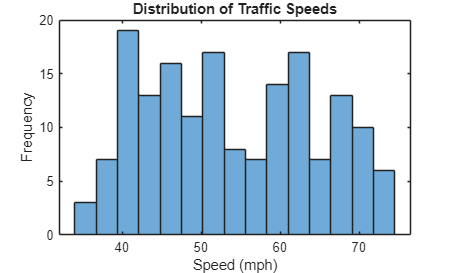


figure;
histogram(speed, 15);                       % Show frequency of speeds
xlabel('Speed (mph)');
ylabel('Frequency');
title('Distribution of Traffic Speeds');

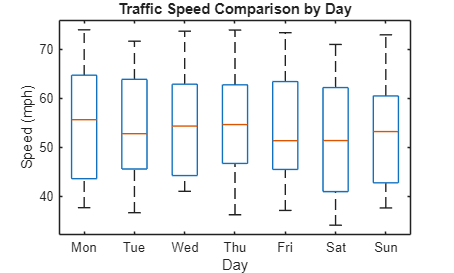


figure;
boxplot(speed, day);                        % Compare speed across days
xlabel('Day');
ylabel('Speed (mph)');
title('Traffic Speed Comparison by Day');

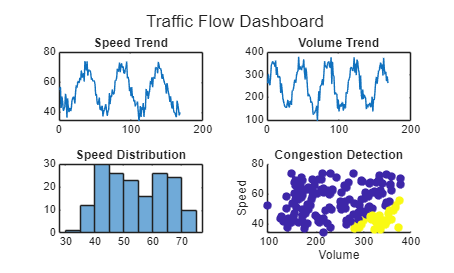


figure;
tiledlayout(2,2);

nexttile
plot(time, speed)
title('Speed Trend')

nexttile
plot(time, volume)
title('Volume Trend')

nexttile
histogram(speed)
title('Speed Distribution')

nexttile
scatter(volume, speed, 40, congested, 'filled')
xlabel('Volume')
ylabel('Speed')
title('Congestion Detection')

sgtitle('Traffic Flow Dashboard')


% Off-peak = high speed + low volume
offPeakTimes = time(speed > avgSpeed & volume < mean(volume));

disp('Best Off-Peak Hours:')

Best Off-Peak Hours:


disp(offPeakTimes)

    24
    25
    26
    27
    28
    29
    30
    31
    32
    33
    34
    35
    36
    37
    74
    78
    94
    95
    96
    97
    99
   101
   129
   131
   132
   133
   134
   135
   136
   137
   138
   139
   140
   141
   142
   143
   144
   145
   146
   147
   148
   150

